%Aplicação do código do Guilherme Freire Roberto
%Rafael Carvalho ultima edição: 11/09/2022

## Limpa o Command Window e o Workspace

clc;
clear;

## Parameters

%Define o diretório autal
Actualdir = pwd;
folds = 10;

%  Imagedir = {
%     'D:\Downloads\ftmp4cvtmb-1\Normal';
%      'D:\Downloads\ftmp4cvtmb-1\Doente'};

%Define os diretórios das imagens
 Imagedir = {
     'D:\TCC\ImagemTeste\Imagens_n_Segmentadas\normal';
     'D:\TCC\ImagemTeste\Imagens_n_Segmentadas\leve';
     'D:\TCC\ImagemTeste\Imagens_n_Segmentadas\moderado'
     'D:\TCC\ImagemTeste\Imagens_n_Segmentadas\grave'
 };


## Define Destination

Destinationfractal = strcat(Imagedir,'\Fractal'); %Define o diretório que será salvo as características

## Calculate fractal attributes

for i=1:length(Imagedir)
    mkdir(Destinationfractal{i})
    cd(strcat(Actualdir,"\codigos-fractal")) %Abre o diretório dos códigos necessário para calcular os atributos
    ScriptPercLACDF3Distances(Imagedir{i},Destinationfractal{i}) %Excuta a função para um classe
    cd(Actualdir)
end

Coletando características Fractais das Imagens -normal
Calculando características fractais - Percolação(1/74)
Starting parallel pool (parpool) using the 'local' profile ...



## Create feature vector


for i=1:length(Imagedir)
    cd(strcat(Actualdir,"\codigos-fractal"))
    disp(strcat('Criado o arquivo .csv de atributos para a classe-',num2str(i)))
    features{i} = SaveCSVPercCLACDF3Distances(Destinationfractal{i},Actualdir,strcat("features-",num2str(i)));
end

Criado o arquivo .csv de atributos para a classe-1
Criado o arquivo .csv de atributos para a classe-2
Criado o arquivo .csv de atributos para a classe-3
Criado o arquivo .csv de atributos para a classe-4


cd(Actualdir)

## Reshape dos atributos fractais

recdir = {};
classdir = {};
%Rec reshape
for i=1:length(Imagedir)
    [xfeat,yfeat] = size(features{i});
    recdir{i} = strcat(Destinationfractal{i},'\reshapeRecPlot');
    mkdir(recdir{i});
    disp(strcat('Gerando Imagens Reshape RecPlot-classe-',num2str(i)))
    reshapeRecPlot(recdir{i},Actualdir,features{i},xfeat)

    %Classical Reshape
    classdir{i} = strcat(Destinationfractal{i},'\reshapeClassical');
    mkdir(classdir{i});
    disp(strcat('Gerando Imagens Reshape Classical-classe-',num2str(i)))
    reshapeClassical(classdir{i},Actualdir,features{i},xfeat)
end

Gerando Imagens Reshape RecPlot-classe-1


Gerando Imagens Reshape Classical-classe-1


Gerando Imagens Reshape RecPlot-classe-2


Gerando Imagens Reshape Classical-classe-2


Gerando Imagens Reshape RecPlot-classe-3


Gerando Imagens Reshape Classical-classe-3


Gerando Imagens Reshape RecPlot-classe-4


Gerando Imagens Reshape Classical-classe-4


## GADF and GASF

- Run plot_gaf.py with properly path, using Onlydata-features

- Find the script in this folder and install necessary librarie and run the code 

% Build GASF amd GADF path
gasfdir = {};
gadfdir = {};
MTFdir = {};
SSMfdir = {};

for i=1:length(Imagedir)
    gasfdir{i} = strcat(Destinationfractal{i},'\GASF');
    gadfdir{i} = strcat(Destinationfractal{i},'\GADF');
    MTFdir{i} = strcat(Destinationfractal{i},'\MTF');
    SSMfdir{i} = strcat(Destinationfractal{i},'\SSM');
end



## Create k-folds for all images

for t=1:1
    
for i=1:length(Imagedir)
    features{1, i}(:,end+1) = i;
    [OrigTrainFolds{i}, OrigTestFolds{i}] = CreateFolds(Imagedir{i}, '.png',false,folds);
end


## Weka Classification

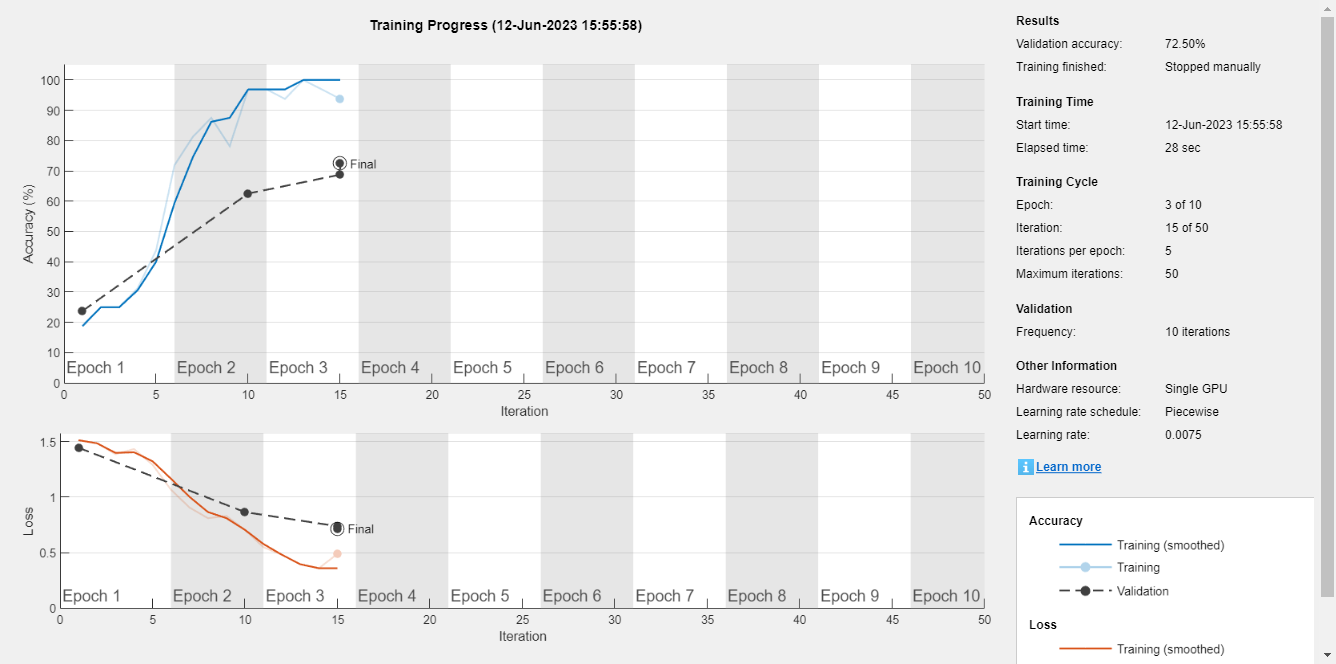

Error using DAGNetwork/activations>iValidateLayerName (line 290)
Layer 'max_pooling2d_1' does not exist.

Error in DAGNetwork/activations>iGetSourceInformation (line 261)
iValidateLayerName( startLayerName, layers );

Error in 

% 
% % Define the weka classifier
% 
% % bayes.BayesNet
% % bayes.NaiveBayes
% % bayes.NaiveBayesMultinomial
% % bayes.HNB
% % functions.GaussianProcesses
% % functions.IsotonicRegression
% % functions.Logistic
% % functions.MultilayerPerceptron
% % functions.RBFNetwork
% % functions.SVMreg
% % lazy.IBk
% % lazy.LBR
% % misc.HyperPipes
% % trees.RandomForest
% 
% [predicted_RandomForest, classProbs_RandomForest, file] = Weka_Classification(Actualdir,Imagedir, OrigTrainFolds, OrigTestFolds,'trees.RandomForest',features,folds);
% [predicted_SMO, classProbs_SMO, file_SMO] = Weka_Classification(Actualdir,Imagedir, OrigTrainFolds, OrigTestFolds,'functions.SMO',features,folds);
% [predicted_Logistic, classProbs_Logistic, file_Logistic] = Weka_Classification(Actualdir,Imagedir, OrigTrainFolds, OrigTestFolds,'functions.Logistic',features,folds);
% [predicted_MultilayerPerceptron, classProbs_MultilayerPerceptron, file_MultilayerPerceptron] = Weka_Classification(Actualdir,Imagedir, OrigTrainFolds, OrigTestFolds,'functions.MultilayerPerceptron',features,folds);


## Create DataFoldSet

Paths_Train = buildpaths(OrigTrainFolds,recdir,classdir,gasfdir,gadfdir,MTFdir,SSMfdir);
Paths_Test = buildpaths(OrigTestFolds,recdir,classdir,gasfdir,gadfdir,MTFdir,SSMfdir);


[OrigTrain, OrigTest] = Datafold(Paths_Train,Paths_Test,folds,3);
[RecPlotTrain, RecPlotTest] = Datafold(Paths_Train,Paths_Test,folds,4);
[ClassicalTrain, ClassicalTest] = Datafold(Paths_Train,Paths_Test,folds,5);
% [GASFTrainGRAYGASFEucl, GASFTestGRAYGASFEucl] = Datafold(Paths_Train,Paths_Test,folds,6);
% [GASFTrainGRAYGASFManh, GASFTestGRAYGASFManh] = Datafold(Paths_Train,Paths_Test,folds,7);
% [GASFTrainGRAYGASFMink, GASFTestGRAYGASFMink] = Datafold(Paths_Train,Paths_Test,folds,8);
% [GADFTrainGRAYGADFEucl, GADFTestGRAYGADFEucl] = Datafold(Paths_Train,Paths_Test,folds,9);
% [GADFTrainGRAYGADFManh, GADFTestGRAYGADFManh] = Datafold(Paths_Train,Paths_Test,folds,folds);
% [GADFTrainGRAYGADFMink, GADFTestGRAYGADFMink] = Datafold(Paths_Train,Paths_Test,folds,11);
% [GADFTrainGRAYGASF, GADFTestGRAYGASF] = Datafold(Paths_Train,Paths_Test,folds,12);
% [GADFTrainGRAYGADF, GADFTestGRAYGADF] = Datafold(Paths_Train,Paths_Test,folds,13);
% [MTFTrainGRAYMTFMink, MTFTestGRAYMTFMink] = Datafold(Paths_Train,Paths_Test,folds,14);
% [MTFTrainGRAYMTFEucl, MTFTestGRAYMTFEucl] = Datafold(Paths_Train,Paths_Test,folds,15);
% [MTFTrainGRAYMTFManh, MTFTestGRAYMTFManh] = Datafold(Paths_Train,Paths_Test,folds,16);
% [MTFTrainMTF, MTFTestMTF] = Datafold(Paths_Train,Paths_Test,folds,17);
% [SSMTrainSSM, SSMTestSSM] = Datafold(Paths_Train,Paths_Test,folds,18);


## Get CNN

%Neural = resnet18;
%Neural = net;
%Neural = resnet50;
Neural = efficientnetb0;



## **Transfer Learning**

if isa(Neural,'SeriesNetwork')
    lgraph = layerGraph(Neural.Layers);
else
    lgraph = layerGraph(Neural);
end

[learnableLayer,classLayer] = findLayersToReplace(lgraph);

newLearnableLayer = fullyConnectedLayer(4, ...
    'Name','new_fc', ...
    'WeightLearnRateFactor',learnableLayer.WeightLearnRateFactor,'WeightsInitializer',learnableLayer.WeightsInitializer,'BiasInitializer',learnableLayer.BiasInitializer,'BiasLearnRateFactor',learnableLayer.BiasLearnRateFactor,...
    'BiasL2Factor',learnableLayer.BiasL2Factor);%,'WeightL2Factor',learnableLayer.Wei3ghtL2Factor);

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);
lgraph = replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer);
Neural = lgraph;

## Run CNN


ME = 10;
ENVIRONMENT = 'GPU';
%numClasses = 2;
numClasses = 4;

[o_Features,o_Pred,o_probs, o_vLossOrig, o_time, o_flat1,o_flat2] = SingleCNN10folds(OrigTrain,OrigTest, Neural,numClasses, ENVIRONMENT, ME,folds);
[rec_Features,rec_Pred,rec_probs, rec_vLossOrig, rec_time,rec_flat1,rec_flat2] = SingleCNN10folds(RecPlotTrain,RecPlotTest, Neural,numClasses, ENVIRONMENT, ME,folds);
[class_Features,class_Pred,class_probs, class_vLossOrig, class_time,class_flat1,class_flat2] = SingleCNN10folds(ClassicalTrain,ClassicalTest, Neural,numClasses, ENVIRONMENT, ME,folds);
%[GASFEucl_Features,GASFEucl_Pred,GASFEucl_probs, GASFEucl_Features_vLossOrig, GASFEucl_Features_time,GasfEu_flat1,GasfEu_flat2] = SingleCNN10folds(GASFTrainGRAYGASFEucl,GASFTestGRAYGASFEucl, Neural,numClasses, ENVIRONMENT, ME,folds);
%[GASFManh_Features,GASFManh_Pred,GASFManh_probs, GASFManh_Features_vLossOrig, GASFManh_Features_time,Gasfmanh_flat1,Gasfmanh_flat2] = SingleCNN10folds(GASFTrainGRAYGASFManh,GASFTestGRAYGASFManh, Neural,numClasses, ENVIRONMENT, ME,folds);
%[GASFMink_Features,GASFMink_Pred,GASFMink_probs, GASFMink_Features_vLossOrig, GASFMink_Features_time,Gasfmink_flat1,Gasfmink_flat2] = SingleCNN10folds(GASFTrainGRAYGASFMink,GASFTestGRAYGASFMink, Neural,numClasses, ENVIRONMENT, ME,folds);
%[GADFEucl_Features,GADFEucl_Pred,GADFEucl_probs, GADFEucl_Features_vLossOrig, GADFEucl_Features_time,Gadfeucl_flat1,Gadfeucl_flat2] = SingleCNN10folds(GADFTrainGRAYGADFEucl,GADFTestGRAYGADFEucl, Neural,numClasses, ENVIRONMENT, ME,folds);
%[GADFManh_Features,GADFManh_Pred,GADFManh_probs, GADFManh_Features_vLossOrig, GADFManh_Features_time,Gadfmanh_flat1,Gadfmanh_flat2] = SingleCNN10folds(GADFTrainGRAYGADFManh,GADFTestGRAYGADFManh, Neural,numClasses, ENVIRONMENT, ME,folds);
%[GADF_Features,GADFMink_Pred,GADFMink_probs, GADFMink_Features_vLossOrig, GADFMink_Features_time,Gadf_flat1,Gadf_flat2] = SingleCNN10folds(GADFTrainGRAYGADFMink,GADFTestGRAYGADFMink, Neural,numClasses, ENVIRONMENT, ME,folds);
%[GRAYMTFMink_Features,GRAYMTFMink_Pred,GRAYMTFMink_probs, GRAYMTFMink_Features_vLossOrig, GRAYMTFMink_Features_time,GrayMTFmink1,GrayMTFmink2] = SingleCNN10folds(MTFTrainGRAYMTFMink,MTFTestGRAYMTFMink, Neural,numClasses, ENVIRONMENT, ME,folds);
%[GRAYMTFEucl_Features,GRAYMTFEucl_Pred,GRAYMTFEucl_probs, GRAYMTFEucl_Features_vLossOrig, GRAYMTFEucl_Features_time,GrayMTFEu1,GrayMTFEu2] = SingleCNN10folds(MTFTrainGRAYMTFEucl,MTFTestGRAYMTFEucl, Neural,numClasses, ENVIRONMENT, ME,folds);
%[GRAYMTFManh_Features,GRAYMTFManh_Pred,GRAYMTFManh_probs, GRAYMTFManh_Features_vLossOrig, GRAYMTFManh_Features_time,GrayMTFManh1,GrayMTFManh2] = SingleCNN10folds(MTFTrainGRAYMTFManh,MTFTestGRAYMTFManh, Neural,numClasses, ENVIRONMENT, ME,folds);
%[MTF_Features,MTF_Pred,MTF_probs, MTF_Features_vLossOrig, MTF_Features_time,MTF_flat1,MTF_flat2] = SingleCNN10folds(MTFTrainMTF,MTFTestMTF, Neural,numClasses, ENVIRONMENT, ME,folds);
%[SSM_Features,SSM_Pred,SSM_probs, SSM_Features_vLossOrig, SSM_Features_time,SMM_flat1,SMM_flat2] = SingleCNN10folds(SSMTrainSSM,SSMTestSSM, Neural,numClasses, ENVIRONMENT, ME,folds);

## Esemble


Result = [];
f = 1;
Maior = {};
%Curva de Probabilidade
% for i=1:5
%     for j=1:5
%         for k=1:5
%             for l=1:5
%                 for m=1:5
%                     for n=1:5
%                         for o=1:5
%                             [Resultado] = NewensembleFNN(OrigTest,o_Features,i-1,rec_Features,j-1,class_Features,k-1,GASFEucl_Features,l-1,GADF_Features,m-1,MTF_Features,n-1,SSM_Features,o-1,folds);
%                             acc = mean(cell2mat(Resultado.acc)); 
%                             acc1 = mean(cell2mat(Resultado.acc1)); 
%                             acc2 = mean(cell2mat(Resultado.acc2)); 
%                             fsocre = mean(cell2mat(Resultado.Fscore));
%                             Maior{f,1} = num2str(i-1);
%                             Maior{f,2} = num2str(j-1);
%                             Maior{f,3} = num2str(k-1);
%                             Maior{f,4} = num2str(l-1);
%                             Maior{f,5} = num2str(m-1);
%                             Maior{f,6} = num2str(n-1);
%                             Maior{f,7} = num2str(o-1);
%                             Maior{f,8} = acc;
%                             Maior{f,9} = fsocre;
%                             Maior{f,10} = acc1;
%                             Maior{f,11} = acc2;
%                             f = f+1;
%                         end
%                     end
%                 end
%             end
%         end
%     end
% end

for i=1:2
    for j=1:2
        for k=1:2
            for l=1:2
                for m=1:2
                    for n=1:2
                        for o=1:2
                            [Resultado] = NewensembleFNN(OrigTest,o_Features,i-1,rec_Features,j-1,class_Features,k-1,folds);
                            acc = mean(cell2mat(Resultado.acc)); 
                            std = sqrt(var(cell2mat(Resultado.acc)));
                            std2 = sqrt(var(cell2mat(Resultado.Fscore)));
                            fsocre = mean(cell2mat(Resultado.Fscore));
                            Maior{f,1} = num2str(i-1);
                            Maior{f,2} = num2str(j-1);
                            Maior{f,3} = num2str(k-1);
                            Maior{f,4} = num2str(l-1);
                            Maior{f,5} = num2str(m-1);
                            Maior{f,6} = num2str(n-1);
                            Maior{f,7} = num2str(o-1);
                            Maior{f,8} = acc;
                            Maior{f,9} = fsocre;
                            Maior{f,10} = std;
                            Maior{f,11} = std2;
                            f = f+1;
                        end
                    end
                end
            end
        end
    end
end




%Tabela = cell2table(Maior,...
 %   "VariableNames",["OrigTest" "rec_Features" "class_Features" "GASF_Features" "GADF_Features" "MTF_Features" "SSM_Features" "Acuracia" "F-socre" "Acuracia1" "Acuracia2"]);

Tabela = cell2table(Maior,...
    "VariableNames",["OrigTest" "rec_Features" "class_Features" "GASF_Features" "GADF_Features" "MTF_Features" "SSM_Features" "Acuracia" "F-socre" "Acuracia1" "Acuracia2"]);


Tabela = sortrows(Tabela,"Acuracia",{'descend'});
idx = Tabela.OrigTest == "1" & Tabela.rec_Features == "0" & Tabela.class_Features == "0" & Tabela.GASF_Features == "0" & Tabela.GADF_Features == "0" & Tabela.MTF_Features == "0" & Tabela.SSM_Features == "0";
idx = Tabela.OrigTest == "0" & Tabela.rec_Features == "0" & Tabela.class_Features == "0" & Tabela.GASF_Features == "0" & Tabela.GADF_Features == "0" & Tabela.MTF_Features == "1" & Tabela.SSM_Features == "1";

Baseline = Tabela(idx,:);

%save()
writetable(Tabela,(['resnet_bin-multi_',int2str(t),'.csv']))
end

## Rename images


a ='D:\Downloads\ftmp4cvtmb-1\Doente';
A =dir( fullfile(a, '*.jpg') );
fileNames = { A.name };
for iFile = 1 : numel( A )
  newName = fullfile(a, sprintf( 'D%01d.jpg', iFile ) );
  movefile( fullfile(a, fileNames{ iFile }), newName );    
end


## Write in csv

for i=1:length(class_flat1)
   table = class_flat1{2, i};
   csvwrite(['Test-Multi-Resnet-Recurrence-avg_pool-','fold',int2str(i),'.csv'],table);
end


for i=1:length(OrigTrain)
   table = OrigTrain{1, i}.Files;
   writecell(table,['TRain-Folds-Files-','fold',int2str(i),'.csv'])
end


